# Supply Chain Capacity model

Jorrit de Jong

4415493

ME54015 - Research Assignment

## General parameters

number of time steps is:

TS_duration = 3600; % [s]
Sim_duration = 30758400; %[s] (one year)
n_T = 8544; % [-]

number of wind turbines is

WT_n = 600; % [-] If Changed, run Simulink generators again

## Open files

n_AT = 12; % Number of annual transfers
n_pre = 100; % Pre order time
% If n_AT is changed: run Simulinks below
if false % If data is unavailable use generators
    open('FailureGenerator.m')
    open('ScheduleGenerator.mlx')
end
%open('Supply_Chain_I.mlx')

## Locations of nodes in supply chain

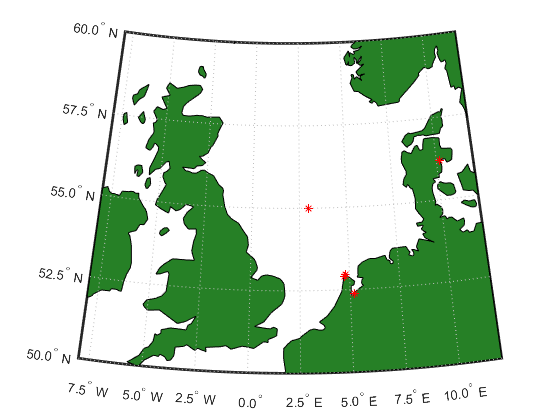

location_dist = [52.382668, 5.197353];
location_terminal = [52.961169, 4.776774];
location_localsupply = [52.910722, 4.756792];
location_wf = [55.000095, 3.000172];
location_source = [56.196680, 10.181246];

worldmap([50 60],[-8 12])
land = shaperead('landareas.shp', 'UseGeoCoords', true);
geoshow(land, 'FaceColor', [0.15 0.5 0.15])
%
geoshow(location_dist(1),location_dist(2),'Marker','*','Color','red')
geoshow(location_terminal(1),location_terminal(2),'Marker','*','Color','red')
geoshow(location_localsupply(1),location_localsupply(2),'Marker','*','Color','red')
geoshow(location_wf(1),location_wf(2),'Marker','*','Color','red')
geoshow(location_source(1),location_source(2),'Marker','*','Color','red')

## Distances

       S DC LW T AI (to)

S

DC

LW

T

AI

(from)

v_vessel = 20; % [km/h]
s_vessel = 300; % [km]
ts_vessel = s_vessel/v_vessel+2;

km2h = 1/60;
truckfactor = 1.6;
initruck = 3;
D = km2h.*truckfactor.*[inf 767 775 774 inf;
                        767 inf 112 124 inf;
                        775 112 inf 16  inf;
                        774 124 16  inf inf;
                        inf inf inf inf inf]+initruck; % [time steps]
ts_sigma_distance = 0.2.*D;